# Plot 20200202 cyOFP benchmarking 2P Field stim

Xiaoyu Lu, xiaoyu.lu@rice.edu St-Pierre Lab, Aug. 2020

## load data

clear;
savepath = '%TEST%\plot_cyOFP_benchmarking_2P_FieldStim';
saveName = '20200202_cyOFPbenchmarking_2PFstim_v20200508.mat';
fNames2P = '2pFstim_20200202_GEVI_screening_cyOFPset_benchmarking_20X_objective.mat';

% Load results table 2P
cyOFPbenchmark2PFstim = load(char(util.filepath(fullfile(savepath,fNames2P))));
lookup_cyOFP = readtable(char(util.filepath(fullfile(savepath,'All control Green GEVIs (P2).xlsx'))),...
    'ReadRowNames',true,'ReadVariableNames',true);

## Rename & reformat table

T_well_2PFstim_cyOFP = cyOFPbenchmark2PFstim.T_well;
for i = 1:height(T_well_2PFstim_cyOFP)
    T_well_2PFstim_cyOFP.Name(i) = libplot.fzmatch(lookup_cyOFP.Name(T_well_2PFstim_cyOFP.wellName(i)));
end
T_well_2PFstim_cyOFP.dFF0_longStim = fillmissing(T_well_2PFstim_cyOFP.dFF0_longStim,'constant',0);
T_well_2PFstim_cyOFP.dFF0_shortStim = fillmissing(T_well_2PFstim_cyOFP.dFF0_shortStim,'constant',0);
T_well_2PFstim_cyOFP.Properties.RowNames = strcat(T_well_2PFstim_cyOFP.Name,'_P2',T_well_2PFstim_cyOFP.wellName);
T_group_2PFstim_cyOFP = libplot.groupWells(T_well_2PFstim_cyOFP);
T_group_2PFstim_cyOFP.Properties.RowNames = T_group_2PFstim_cyOFP.Name;
% save(fullfile(savepath,saveName),'T_well_2PFstim_cyOFP','T_group_2PFstim_cyOFP');

## Designate the table to-be-plotted

pltTable = T_group_2PFstim_cyOFP;
dt = {'Area_Mean','dFF0_shortStim_Mean', 'dFF0_longStim_Mean', ...
    'dFF0_shortStim_Mean', 'GRratioMean_Mean', 'Bleachingratio_total_Mean',...
    'TgtAUC_sig_NormaltoRandT_Mean'}; %% datatips

## Figure 2P Fstim dF/F0

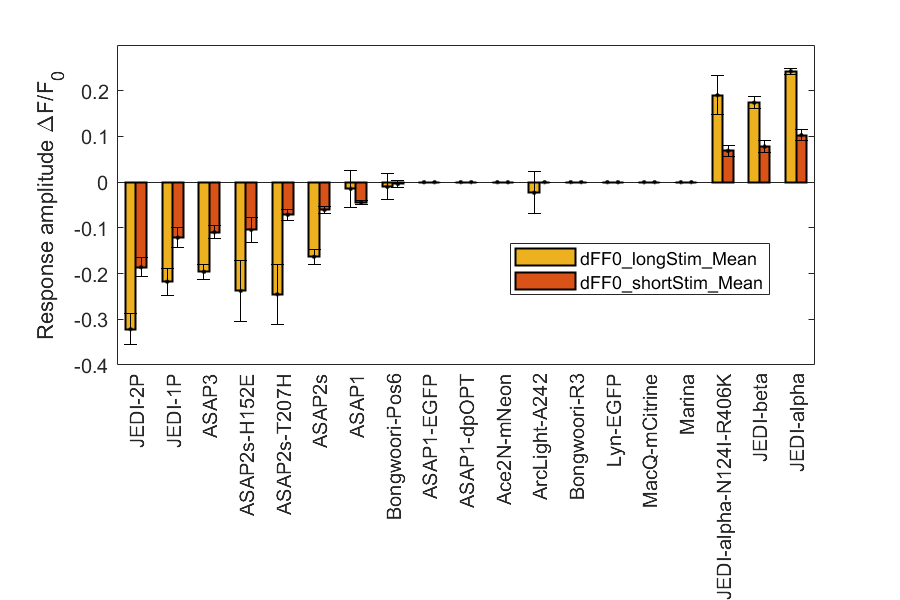

% Sort on dF/F0 of 1ms 60V stimulation
SortOn = 'dFF0_shortStim_Mean'; % Input Sorting Criteria
% Absolute value
cmap = [0.9290, 0.6940, 0.1250; 0.8500, 0.3250, 0.0980];
libplot.formattedBar(pltTable, ...
    'dFF0_longStim_Mean', 'dFF0_shortStim_Mean', ...
    'pp1std','dFF0_longStim_STD',...
    'pp2std', 'dFF0_shortStim_STD', ...
    'sort_on', SortOn, ...
    'datatip', dt,...
    'ylabel', 'Response amplitude \DeltaF/F_0', ...
    'colormap', cmap);

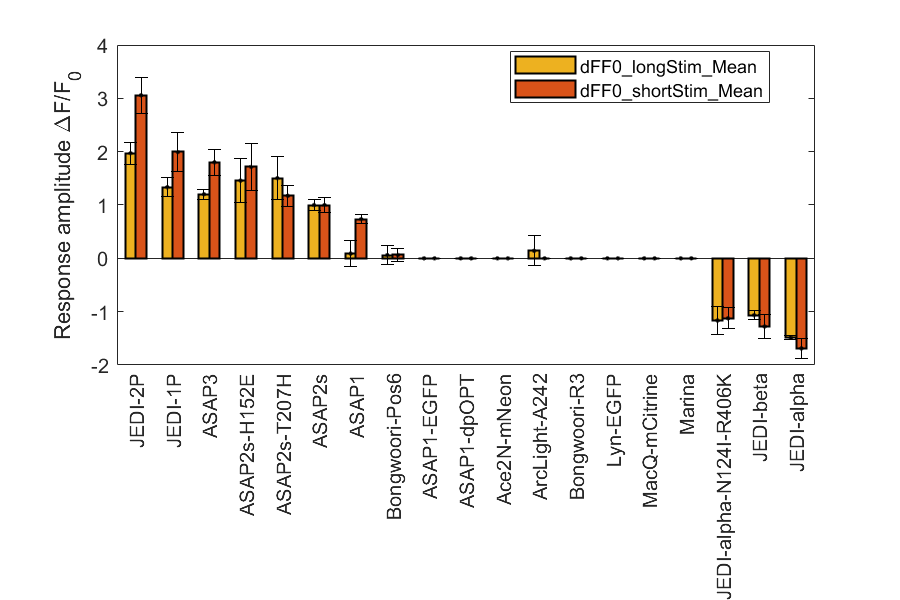

% Normalized to ASAP2s
libplot.formattedBar(pltTable, ...
    'dFF0_longStim_Mean', 'dFF0_shortStim_Mean', ...
    'pp1std','dFF0_longStim_STD',...
    'pp2std', 'dFF0_shortStim_STD', ...
    'sort_on', SortOn, ...
    'datatip', dt,...
    'norm2ctrl', 'ASAP2s', ...
    'ylabel', 'Response amplitude \DeltaF/F_0', ...
    'colormap', cmap);

## Figure 2P relative brightness

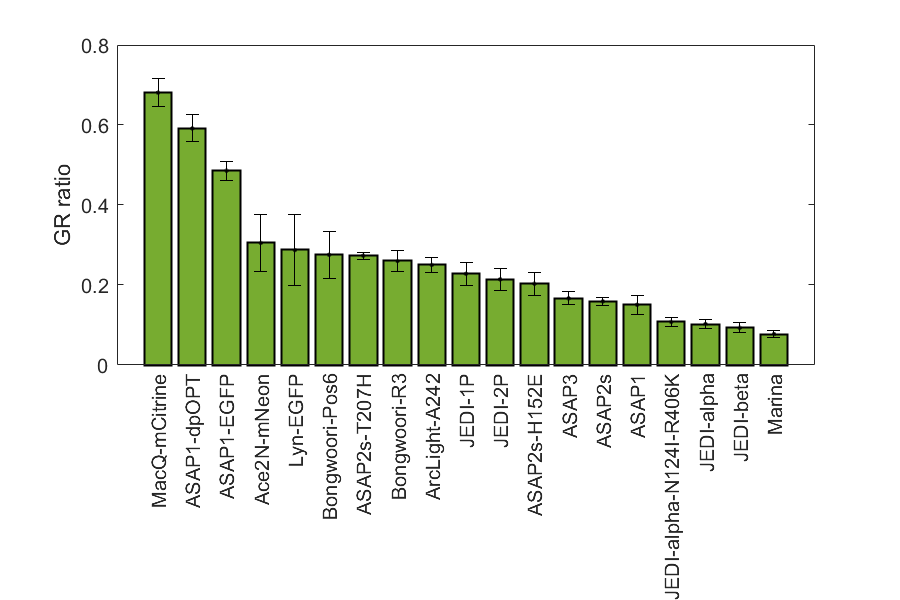

SortOn = 'GRratioMean_Mean';
cmap = [0.4660, 0.6740, 0.1880];
% Absolute value
libplot.formattedBar(pltTable, 'GRratioMean_Mean', ...
    'pp1std','GRratioMean_STD', ...
    'sort_on', SortOn, ...
    'sort_direction', 'descend', ...
    'ylabel', 'GR ratio',...
    'colormap', cmap, ...
    'datatip', dt);

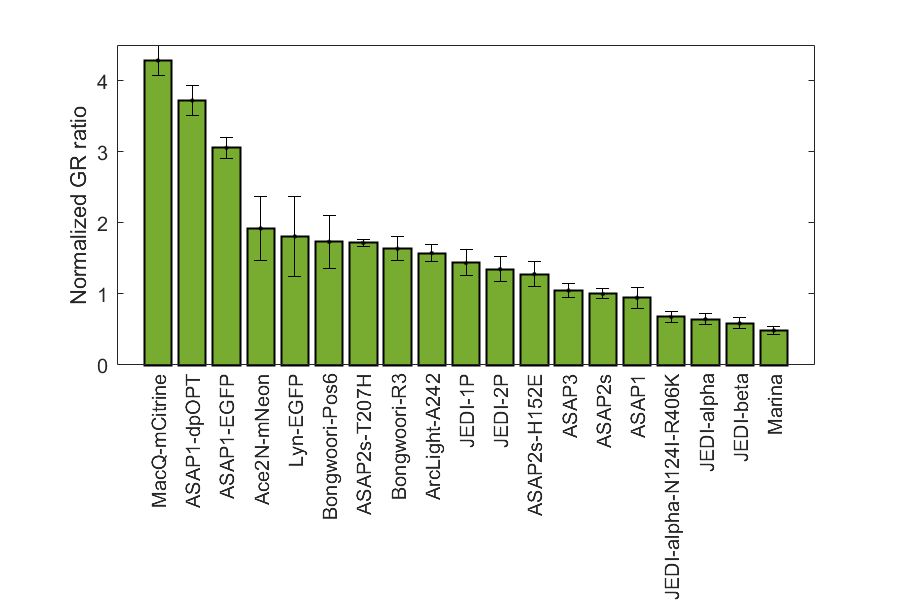

% Normalized to ASAP2s
libplot.formattedBar(pltTable, 'GRratioMean_Mean', ...
    'pp1std','GRratioMean_STD', ...
    'sort_on', SortOn, ...
    'sort_direction', 'descend', ...
    'ylabel', 'Normalized GR ratio',...
    'norm2ctrl', 'ASAP2s', ...
    'colormap', cmap, ...
    'datatip', dt);

## Figure 2P photostability

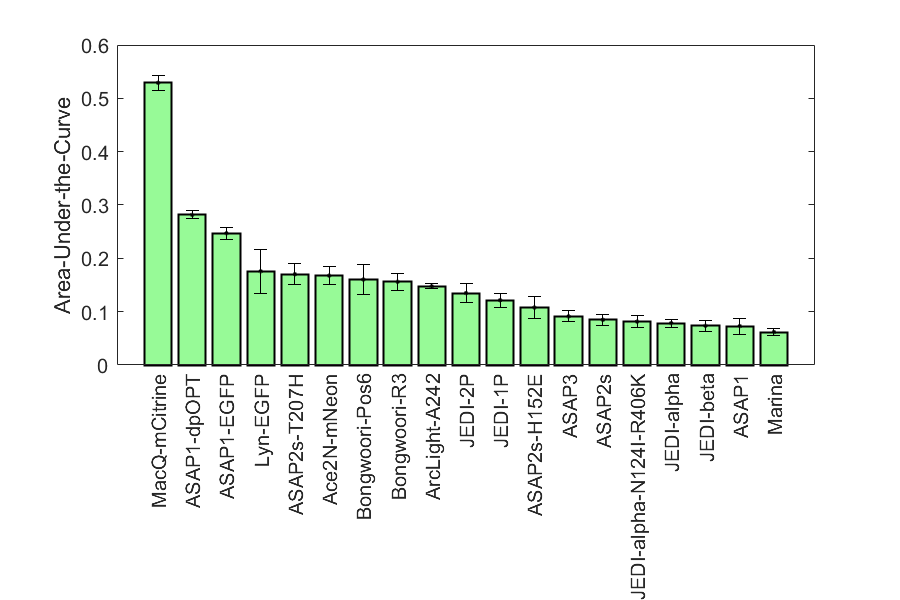

% Area-under-the-curve
SortOn = 'TgtAUC_sig_NormaltoRandT_Mean';
cmap = [152,251,152]./256;
libplot.formattedBar(pltTable,'TgtAUC_sig_NormaltoRandT_Mean',...
    'pp1std', 'TgtAUC_sig_NormaltoRandT_STD', ...
    'sort_on', SortOn, ...
    'sort_direction', 'descend', ...
    'ylabel', 'Area-Under-the-Curve', ...
    'colormap', cmap, ...
    'datatip', dt);

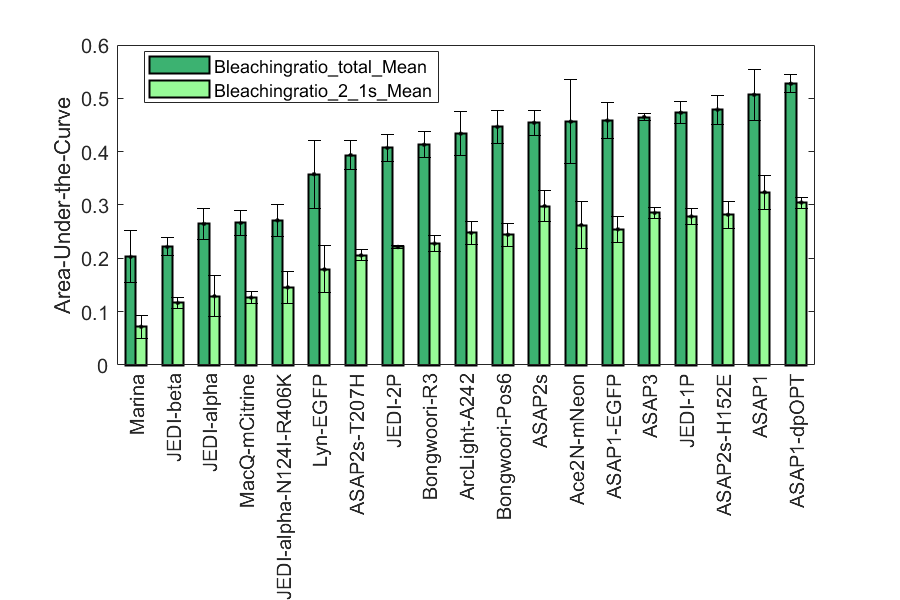

% Bleaching ratio
SortOn = 'Bleachingratio_total_Mean';
cmap = [60,179,113;152,251,152]./256;
libplot.formattedBar(pltTable, 'Bleachingratio_total_Mean', 'Bleachingratio_2_1s_Mean', ...
    'pp1std', 'Bleachingratio_total_STD', ...
    'pp2std', 'Bleachingratio_2_1s_STD', ...
    'sort_on', SortOn, ...
    'ylabel','Area-Under-the-Curve', ...
    'colormap', cmap, ...
    'datatip', dt);